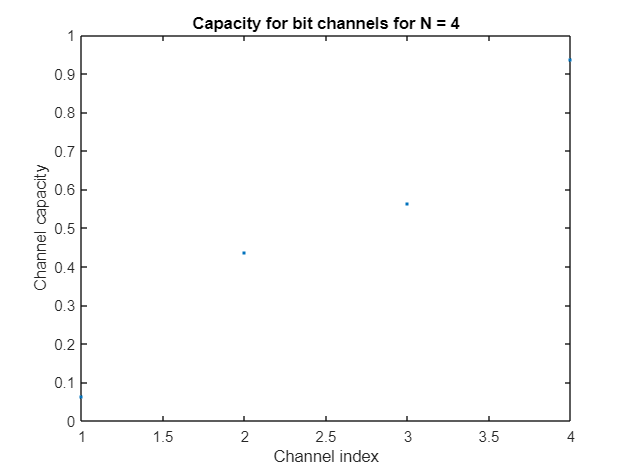

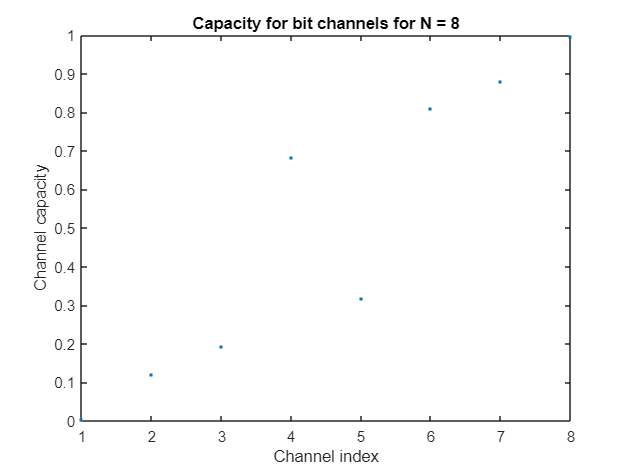

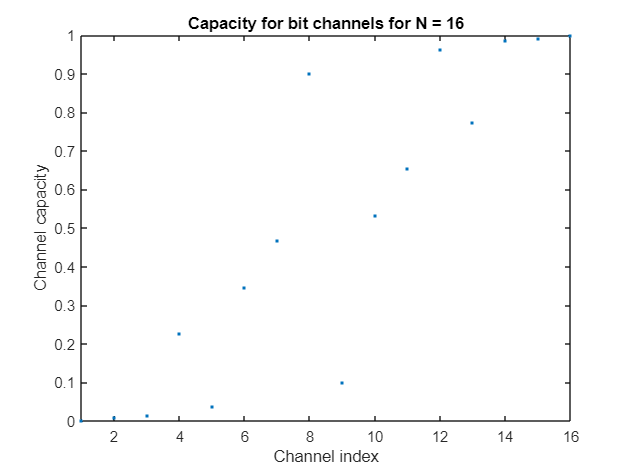

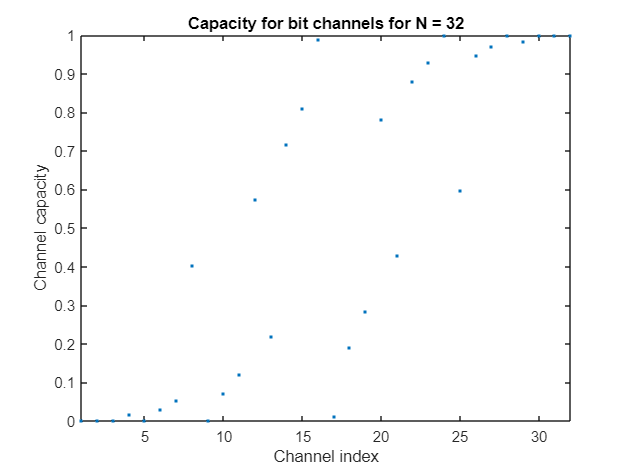

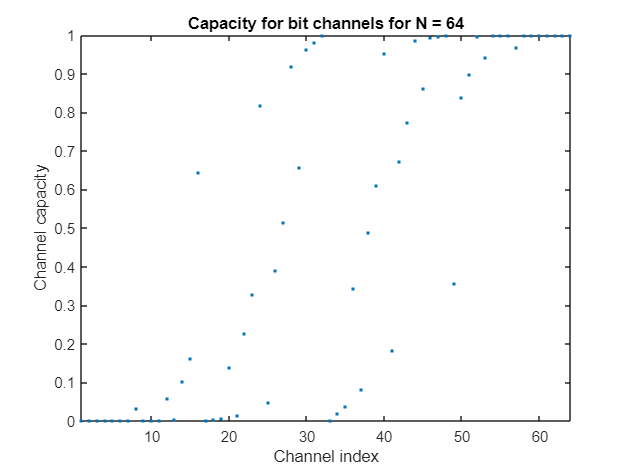

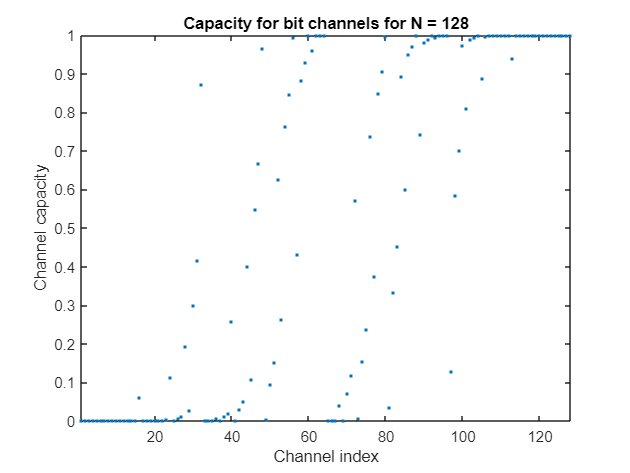

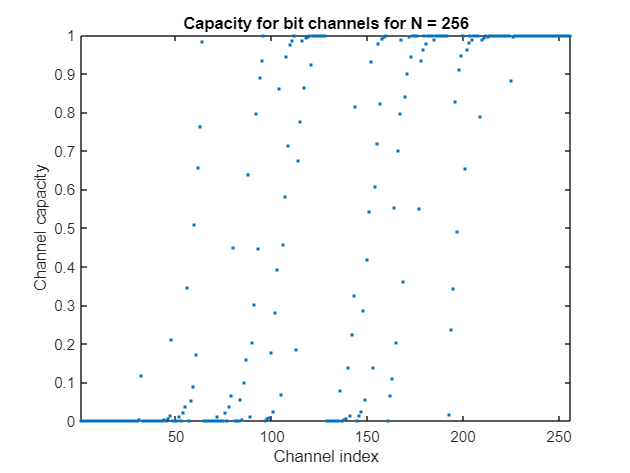

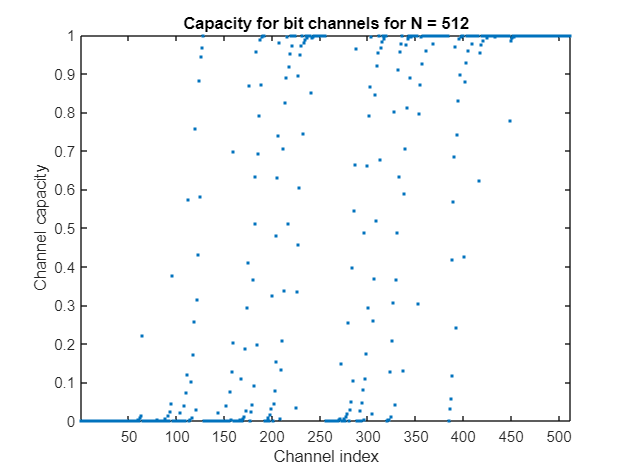

clearvars;
close all;
clc;

p = 0.5;
I = 1 - p;
hr = 2:1:10;

for h = hr
    nodes = 2^(h + 1) - 1;
    I_vec = zeros(nodes, 1);
    I_vec(1) = I;
    i = 1;
    while 2 * i + 1 <= nodes
        I_vec(2 * i) = I_vec(i)^2;
        I_vec(2 * i + 1) = 2 * I_vec(i) - I_vec(i)^2;
        i = i + 1;
    end
    polarized_channels = I_vec(i:end);
    figure;
    plot(1:length(polarized_channels), polarized_channels, '.');
    ylabel('Channel capacity');
    xlabel('Channel index');
    title(['Capacity for bit channels for N = ', num2str(2^h)]);
    xlim([1,2^h]);
end